## Condiciones iniciales de avance

clear

syms a1(t) a2(t) a3(t) a4(t) a5(t) T A
syms v1(t) v2(t) v3(t) v4(t) v5(t) 
syms x1(t) x2(t) x3(t) x4(t) x5(t)
assume(T>0)
assume(A>0)
g=9.81;
xMax=0.1

xMax = 0.1000

aMax=g/6

aMax = 0.9810

A=aMax;


## Aceleración

a1(t)=10*A/T*t;

a2(t)=A;

a3(t)=-10*A/T*t;
Ca3=A-a3(4*T/10);
a3(t)=a3(t)+Ca3;
a4(t)=-A;
a5(t)=10*A/T*t;
Ca5=a4(9*T/10)-a5(9*T/10);
a5(t)=a5(t)+Ca5;
fprintf('Función de aceleración:')

Función de aceleración:

a(t)=piecewise((0<=t<T/10),a1,(T/10<=t<4*T/10),a2,(4*T/10<=t<6*T/10),a3,(6*T/10<=t<9*T/10),a4,(9*T/10<=t<=T),a5)

$$a(t) = \begin{array}{l} \left\{ \begin{array}{cl} \sigma_{1} & \text{ if }10\,t<T\wedge 0\leq t\\ \frac{981}{1000} & \text{ if }T\leq 10\,t\wedge 5\,t<2\,T\\ \frac{981}{200}-\sigma_{1} & \text{ if }5\,t<3\,T\wedge 2\,T\leq 5\,t\\ -\frac{981}{1000} & \text{ if }10\,t<9\,T\wedge 3\,T\leq 5\,t\\ \sigma_{1}-\frac{981}{100} & \text{ if }t\leq T\wedge 9\,T\leq 10\,t \end{array}\right.\\ \mathrm{where}\\ \sigma_{1}=\frac{981\,t}{100\,T} \end{array}$$

## Velocidad

v1(t)=int(a1);

v2(t)=int(a2);
Cv2=v1(T/10)-v2(T/10);
v2(t)=v2(t)+Cv2;

v3(t)=int(a3);
Cv3=v2(4*T/10)-v3(4*T/10);
v3(t)=v3(t)+Cv3;

v4(t)=int(a4);
Cv4=v3(6*T/10)-v4(6*T/10);
v4(t)=v4(t)+Cv4;

v5(t)=int(a5);
Cv5=v4(9*T/10)-v5(9*T/10);
v5(t)=v5(t)+Cv5;

fprintf('Función de velocidad:')

Función de velocidad:

v(t)=piecewise((0<=t<T/10),v1,(T/10<=t<4*T/10),v2,(4*T/10<=t<6*T/10),v3,(6*T/10<=t<9*T/10),v4,(9*T/10<=t<=T),v5)

$$v(t) = \left\{ \begin{array}{cl} \frac{981\,t^{2}}{200\,T} & \text{ if }10\,t<T\wedge 0\leq t\\ \frac{981\,t}{1000}-\frac{981\,T}{20000} & \text{ if }T\leq 10\,t\wedge 5\,t<2\,T\\ -\frac{16677\,T}{20000}-\frac{t\,\left(\frac{981\,t}{T}-981\right)}{200} & \text{ if }5\,t<3\,T\wedge 2\,T\leq 5\,t\\ \frac{18639\,T}{20000}-\frac{981\,t}{1000} & \text{ if }10\,t<9\,T\wedge 3\,T\leq 5\,t\\ \frac{981\,T}{200}+\frac{t\,\left(\frac{981\,t}{2\,T}-981\right)}{100} & \text{ if }t\leq T\wedge 9\,T\leq 10\,t \end{array}\right.$$

## Desplazamiento


x1(t)=int(v1);

x2(t)=int(v2);
Cx2=x1(T/10)-x2(T/10);
x2(t)=x2(t)+Cx2;

x3(t)=int(v3);
Cx3=x2(4*T/10)-x3(4*T/10);
x3(t)=x3(t)+Cx3;

x4(t)=int(v4);
Cx4=x3(6*T/10)-x4(6*T/10);
x4(t)=x4(t)+Cx4;

x5(t)=int(v5);
Cx5=x4(9*T/10)-x5(9*T/10);
x5(t)=x5(t)+Cx5;

fprintf('Función de desplazamiento:')

Función de desplazamiento:

x(t)=piecewise((0<=t<T/10),x1,(T/10<=t<4*T/10),x2,(4*T/10<=t<6*T/10),x3,(6*T/10<=t<9*T/10),x4,(9*T/10<=t<=T),x5)

$$x(t) = \left\{ \begin{array}{cl} \frac{327\,t^{3}}{200\,T} & \text{ if }10\,t<T\wedge 0\leq t\\ \frac{327\,T^{2}}{200000}-\frac{981\,t\,\left(T-10\,t\right)}{20000} & \text{ if }T\leq 10\,t\wedge 5\,t<2\,T\\ \frac{4251\,T^{2}}{40000}-\frac{327\,t\,\left(51\,T^{2}-150\,T\,t+100\,t^{2}\right)}{20000\,T} & \text{ if }5\,t<3\,T\wedge 2\,T\leq 5\,t\\ \frac{981\,t\,\left(19\,T-10\,t\right)}{20000}-\frac{49377\,T^{2}}{200000} & \text{ if }10\,t<9\,T\wedge 3\,T\leq 5\,t\\ \frac{327\,t\,\left(3\,T^{2}-3\,T\,t+t^{2}\right)}{200\,T}-\frac{3597\,T^{2}}{2500} & \text{ if }t\leq T\wedge 9\,T\leq 10\,t \end{array}\right.$$

## Solución de tMax

f=xMax/2==x(T/2);

tMax=solve(f,T);


a=subs(a,T,tMax);
v=subs(v,T,tMax);
x=subs(x,T,tMax);
a(t)=piecewise((0<=t<tMax),a(t),(tMax<=t<=2*tMax),-a(t-tMax))

$$a(t) = \begin{array}{l} \left\{ \begin{array}{cl} \sigma_{1} & \text{ if }t\in \left[0,\frac{\sqrt{545}}{327}\right)\\ \frac{981}{1000} & \text{ if }t\in \left[\frac{\sqrt{545}}{327},\sigma_{6}\right)\\ \frac{981}{200}-\sigma_{1} & \text{ if }t\in \left[\sigma_{6},\sigma_{8}\right)\\ -\frac{981}{1000} & \text{ if }t\in \left[\sigma_{8},\sigma_{7}\right)\\ \sigma_{1}-\frac{981}{100} & \text{ if }t\in \left[\sigma_{7},\sigma_{10}\right)\\ -\sigma_{9} & \text{ if }t\in \left[\sigma_{10},\sigma_{5}\right)\\ -\frac{981}{1000} & \text{ if }t\in \left[\sigma_{5},\sigma_{4}\right)\\ \sigma_{9}-\frac{981}{200} & \text{ if }t\in \left[\sigma_{4},\sigma_{3}\right)\\ \frac{981}{1000} & \text{ if }t\in \left[\sigma_{3},\sigma_{2}\right)\\ \frac{981}{100}-\sigma_{9} & \text{ if }\sigma_{2}\leq t\wedge t\leq \frac{20\,\sqrt{545}}{327} \end{array}\right.\\ \mathrm{where}\\ \sigma_{1}=\frac{2943\,\sqrt{545}\,t}{5000}\\ \sigma_{2}=\frac{19\,\sqrt{545}}{327}\\ \sigma_{3}=\frac{16\,\sqrt{545}}{327}\\ \sigma_{4}=\frac{14\,\sqrt{545}}{327}\\ \sigma_{5}=\frac{11\,\sqrt{545}}{327}\\ \sigma_{6}=\frac{4\,\sqrt{545}}{327}\\ \sigma_{7}=\frac{3\,\sqrt{545}}{109}\\ \sigma_{8}=\frac{2\,\sqrt{545}}{109}\\ \sigma_{9}=\frac{2943\,\sqrt{545}\,\left(t-\sigma_{10}\right)}{5000}\\ \sigma_{10}=\frac{10\,\sqrt{545}}{327} \end{array}$$

v(t)=piecewise((0<=t<tMax),v(t),(tMax<=t<=2*tMax),-v(t-tMax))

$$v(t) = \begin{array}{l} \left\{ \begin{array}{cl} \frac{2943\,\sqrt{545}\,t^{2}}{10000} & \text{ if }t\in \left[0,\frac{\sqrt{545}}{327}\right)\\ \frac{981\,t}{1000}-\frac{3\,\sqrt{545}}{2000} & \text{ if }t\in \left[\frac{\sqrt{545}}{327},\sigma_{6}\right)\\ -\sigma_{1}-\frac{t\,\left(\frac{2943\,\sqrt{545}\,t}{50}-981\right)}{200} & \text{ if }t\in \left[\sigma_{6},\sigma_{8}\right)\\ \frac{57\,\sqrt{545}}{2000}-\frac{981\,t}{1000} & \text{ if }t\in \left[\sigma_{8},\sigma_{7}\right)\\ \sigma_{9}+\frac{t\,\left(\frac{2943\,\sqrt{545}\,t}{100}-981\right)}{100} & \text{ if }t\in \left[\sigma_{7},\sigma_{11}\right)\\ -\frac{2943\,\sqrt{545}\,{\left(t-\sigma_{11}\right)}^{2}}{10000} & \text{ if }t\in \left[\sigma_{11},\sigma_{5}\right)\\ \frac{63\,\sqrt{545}}{2000}-\frac{981\,t}{1000} & \text{ if }t\in \left[\sigma_{5},\sigma_{4}\right)\\ \sigma_{1}+\frac{\left(t-\sigma_{11}\right)\,\left(\frac{\sigma_{10}}{50}-981\right)}{200} & \text{ if }t\in \left[\sigma_{4},\sigma_{3}\right)\\ \frac{981\,t}{1000}-\frac{117\,\sqrt{545}}{2000} & \text{ if }t\in \left[\sigma_{3},\sigma_{2}\right)\\ -\sigma_{9}-\frac{\left(t-\sigma_{11}\right)\,\left(\frac{\sigma_{10}}{100}-981\right)}{100} & \text{ if }\sigma_{2}\leq t\wedge t\leq \frac{20\,\sqrt{545}}{327} \end{array}\right.\\ \mathrm{where}\\ \sigma_{1}=\frac{51\,\sqrt{545}}{2000}\\ \sigma_{2}=\frac{19\,\sqrt{545}}{327}\\ \sigma_{3}=\frac{16\,\sqrt{545}}{327}\\ \sigma_{4}=\frac{14\,\sqrt{545}}{327}\\ \sigma_{5}=\frac{11\,\sqrt{545}}{327}\\ \sigma_{6}=\frac{4\,\sqrt{545}}{327}\\ \sigma_{7}=\frac{3\,\sqrt{545}}{109}\\ \sigma_{8}=\frac{2\,\sqrt{545}}{109}\\ \sigma_{9}=\frac{3\,\sqrt{545}}{20}\\ \sigma_{10}=2943\,\sqrt{545}\,\left(t-\sigma_{11}\right)\\ \sigma_{11}=\frac{10\,\sqrt{545}}{327} \end{array}$$

x(t)=piecewise((0<=t<tMax),x(t),(tMax<=t<=2*tMax),x(tMax)-x(t-tMax))

tMax=2*tMax;
fprintf('Tiempo de ciclo %.3f s',tMax)

Tiempo de ciclo 1.428 s

## Gráficas

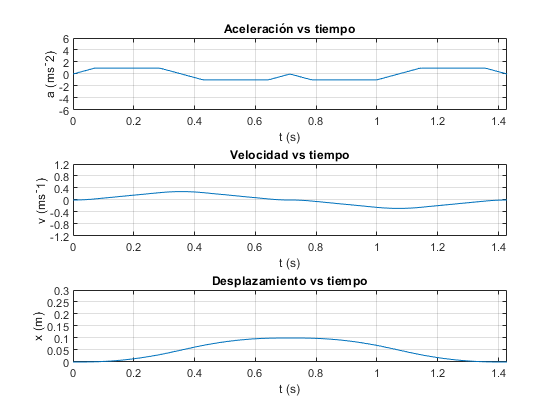

ts=linspace(0,tMax,200);
subplot(3,1,1)

plot(ts,a(ts))
title('Aceleración vs tiempo')
grid on
xlabel('t (s)')
ylabel('a (ms^-2)')
ylim([-6 6])
xlim([0 double(tMax)])
yticks(-6:2:6)


subplot(3,1,2)

plot(ts,v(ts))
title('Velocidad vs tiempo')
grid on
xlabel('t (s)')
ylabel('v (ms^-1)')
ylim([-1.2 1.2])
xlim([0 double(tMax)])
yticks(-1.2:0.4:1.2)

subplot(3,1,3)

plot(ts,x(ts))
title('Desplazamiento vs tiempo')
grid on
xlabel('t (s)')
ylabel('x (m)')
ylim([0 0.30])
xlim([0 double(tMax)])
yticks(0:0.05:0.30)

ans = 0.2801




%MAA=table(double(ts'),double(x(ts)')*1000)

%writetable(MAA,'docTXT/MAvance.txt','delimiter',' ', 'WriteVariableNames', true)





## Tranformación movimiento lineal a radial


Velocidad_Linear_Max=0.75

Velocidad_Linear_Max = 0.7500

Velocidad_Radial_Max_RPM=1800

Velocidad_Radial_Max_RPM = 1800

Velocidad_Radial_Max_rads=Velocidad_Radial_Max_RPM*pi/30

Velocidad_Radial_Max_rads = 188.4956


Razon_VR_VL=Velocidad_Radial_Max_rads/Velocidad_Linear_Max

Razon_VR_VL = 251.3274



aRadial=double(a(ts)*Razon_VR_VL);
vRadial=double(v(ts)*Razon_VR_VL);
xRadial=double(x(ts)*Razon_VR_VL);


vRadial2=vRadial*30/pi

vRadial2 =          0    0.8489    3.3956    7.6401   13.5823   21.2224   30.5603   41.5959   54.3294   68.7606   84.8875  101.7805  118.6736  135.5666  152.4596  169.3527  186.2457  203.1387  220.0318  236.9248  253.8178  270.7109  287.6039  304.4969  321.3900  338.2830  355.1760  372.0691  388.9621  405.8552  422.7482  439.6412  456.5343  473.4273  490.3203  507.2134  524.1064  540.9994  557.8925  574.7855  591.6446  607.3492  621.3559  633.6649  644.2761  653.1895  660.4052  665.9230  669.7430  671.8653


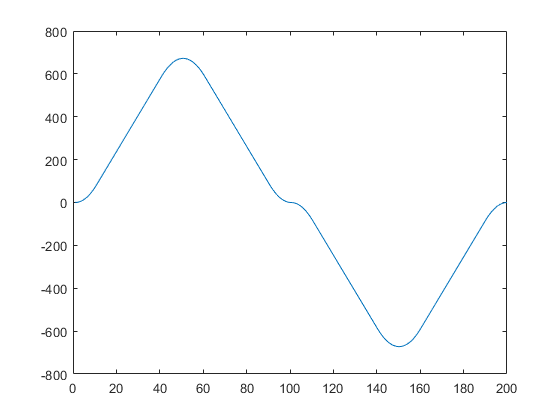


figure()
plot(vRadial2)

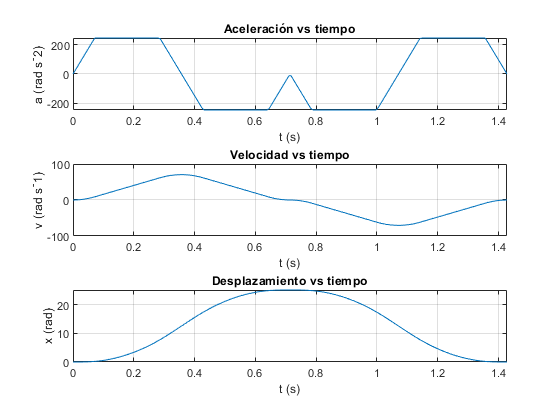



figure()
subplot(3,1,1)

plot(ts,aRadial)
title('Aceleración vs tiempo')
grid on
xlabel('t (s)')
ylabel('a (rad s^-2)')
xlim([0 double(tMax)])

subplot(3,1,2)
plot(ts,vRadial)
title('Velocidad vs tiempo')
grid on
xlabel('t (s)')
ylabel('v (rad s^-1)')
xlim([0 double(tMax)])

subplot(3,1,3)

plot(ts,xRadial)
title('Desplazamiento vs tiempo')
grid on
xlabel('t (s)')
ylabel('x (rad)')
xlim([0 double(tMax)])